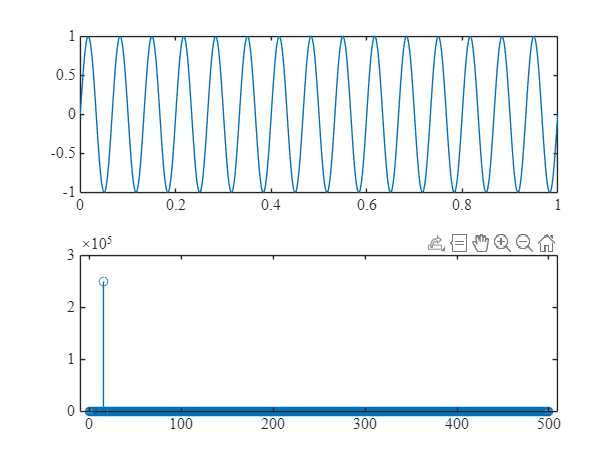

clear;clc;

f = 15; dt = 0.001;
t = 0:dt:1;
signal = sin(2*pi*f*t);
fft_signal = fft(signal);

N = length(t); F = (0:N-1)/N/dt;

figure;
subplot(2, 1, 1);
plot(t, signal);
subplot(2, 1, 2);
stem(F(1:round(N/2)), abs(fft_signal(1:round(N/2))).^2);

% xlim([0 50]);